# SNW_VFI_PARAM Tiny Solution Analysis Consumption Rule Changes

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**snw_vfi_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_vfi_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function analyzes the effects of the consumption allocation rule on model choices. The consumption allocation rule could be such that been married and having children does not change contemperaneous utility, only changes income. 

- Household consumption is within household public good. Having children and been married only impacts income

- Marginal utility of household consumption is higher when there are more kids and given marriage with uniform division of consumption for each household member, and the household planner cares about household consumption divided by the number of individuals in the household

- Consumption divide by square root of household member count. 

## Public Good: Test SNW_VFI_MAIN Tiny with cons_allocation_rule = 0 

Call the function with defaults.

mp_param = snw_mp_param('default_tiny');
mp_param('cons_allocation_rule') = 0

mp_param =   Map with properties:

        Count: 37
      KeyType: char
    ValueType: any


[V_VFI_car0,ap_VFI_car0,cons_VFI_car0,exitflag_VFI_car0] = snw_vfi_main(mp_param);

SNW_VFI_MAIN: Finished Age Group:7 of 7
SNW_VFI_MAIN: Finished Age Group:6 of 7
SNW_VFI_MAIN: Finished Age Group:5 of 7
SNW_VFI_MAIN: Finished Age Group:4 of 7
SNW_VFI_MAIN: Finished Age Group:3 of 7
SNW_VFI_MAIN: Finished Age Group:2 of 7
SNW_VFI_MAIN: Finished Age Group:1 of 7
Elapsed time is 74.297762 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=;default_tiny;SNW_MP_CONTROL=;default_base


## Tiny Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 28:16:92, 100];
agrid = mp_param('agrid')';
eta_H_grid = mp_param('eta_H_grid')';
eta_S_grid = mp_param('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'Hshock', eta_H_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 3; % how many shock legends to show
mp_support_graph('st_rounding') = '6.2f'; % format shock legend

#### MEAN(VAL(A,Z)), MEAN(AP(A,Z)), MEAN(C(A,Z))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(A,Z))", V_VFI_car0, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_Hshock__0_72413    mean_Hshock__0_36206    mean_Hshock_0    mean_Hshock_0_36206    mean_Hshock_0_72413
    _____    _______    ____________________    ____________________    _____________    ___________________    ___________________

      1            0          -0.93669                -0.65103            -0.39255            -0.17249               0.011637      
      2      0.26063          -0.15381               0.0059109             0.16167             0.30694                0.44775      
      3        2.085            1.0036                  1.0355              1.0725              1.1135                  1.157      
      4        7.037            1.4494              

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z))", ap_VFI_car0, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_Hshock__0_72413    mean_Hshock__0_36206    mean_Hshock_0    mean_Hshock_0_36206    mean_Hshock_0_72413
    _____    _______    ____________________    ____________________    _____________    ___________________    ___________________

      1            0         0.0053887                0.020373            0.044588             0.07222                0.13703      
      2      0.26063           0.10449                 0.12662             0.13162             0.16519                0.27638      
      3        2.085            1.3922                  1.3988              1.3988              1.3988                 1.3988      
      4        7.037            4.6388               

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z))", cons_VFI_car0, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_Hshock__0_72413    mean_Hshock__0_36206    mean_Hshock_0    mean_Hshock_0_36206    mean_Hshock_0_72413
    _____    _______    ____________________    ____________________    _____________    ___________________    ___________________

      1            0          0.67019                 0.75541              0.87257             1.0451                 1.2646       
      2      0.26063             1.01                  1.0869               1.2222              1.388                 1.5604       
      3        2.085           2.7576                  2.8475               2.9853             3.1821                 3.4634       
      4        7.037           7.6909                 

Graph Mean Values:

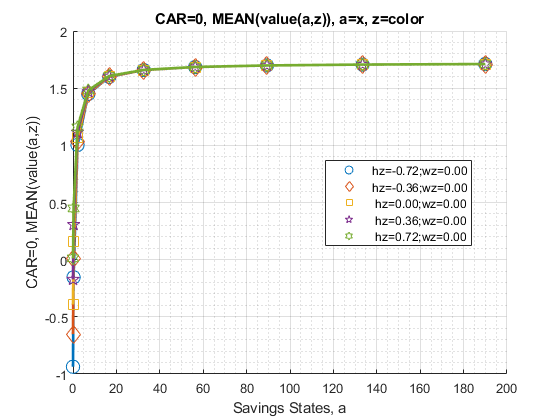

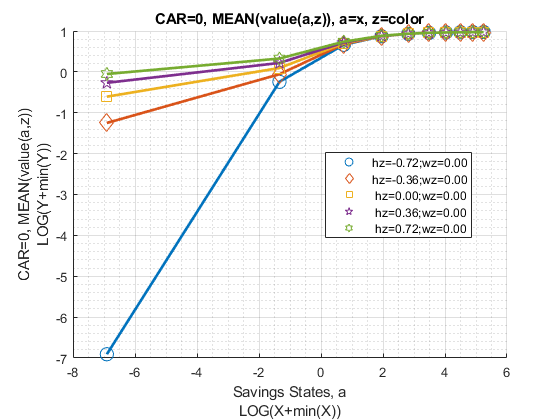

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(value(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(value(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Savings Choices:

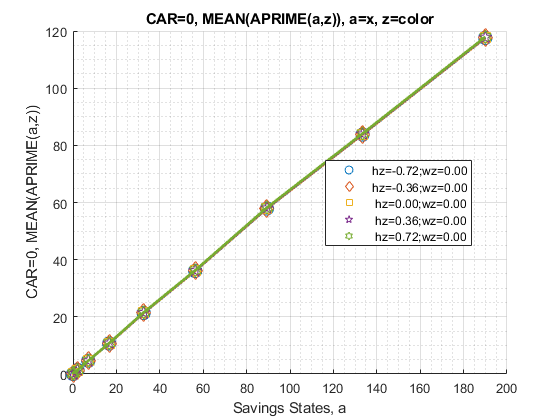

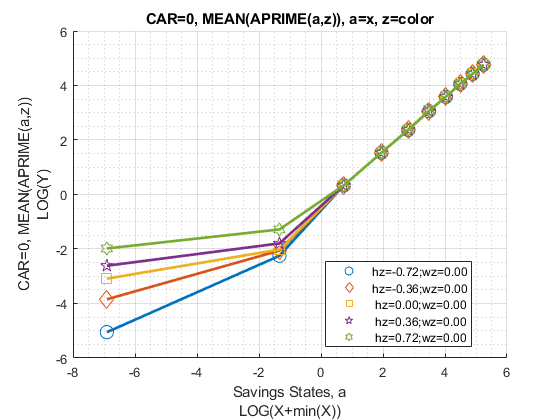

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(APRIME(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(APRIME(a,z))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption:

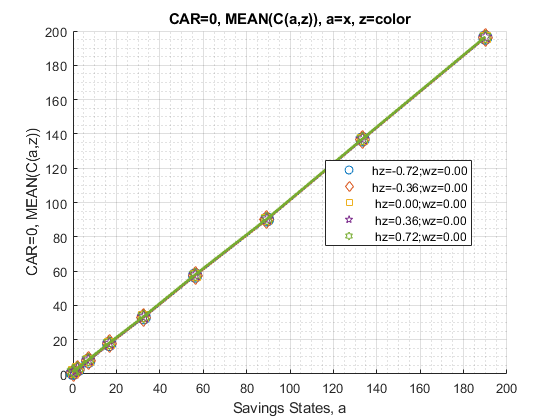

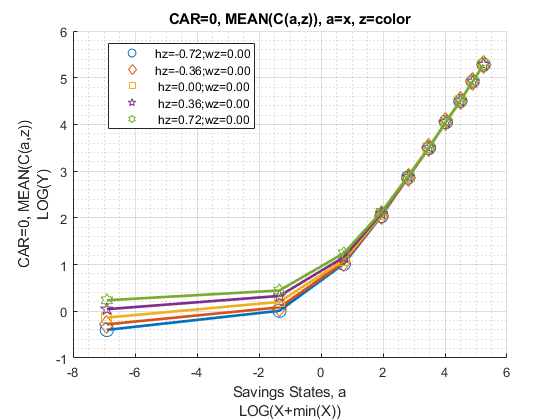

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(C(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(C(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(KM,J))", round(V_VFI_car0,4), true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        1.7469         1.6788         1.5065         1.1967         0.71067        0.59417        0.59208   
      2       2        0        1.7469         1.6788         1.5065         1.1967         0.71067        0.59417        0.59208   
      3       3        0        1.7469         1.6788         1.5065         

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(KM,J))", ap_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        52.769         52.776         50.875         39.985         29.647         8.4444            0      
      2       2        0        52.769         52.776         50.875         39.985         29.647         8.4444            0      
      3       3        0        52.769         52.776         50.875         3

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(KM,J))", cons_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        35.046         35.288         37.456         48.312         57.793         78.995          87.439   
      2       2        0        35.046         35.288         37.456         48.312         57.793         78.995          87.439   
      3       3        0        35.046         35.288         37.456         48

Graph Mean Values:

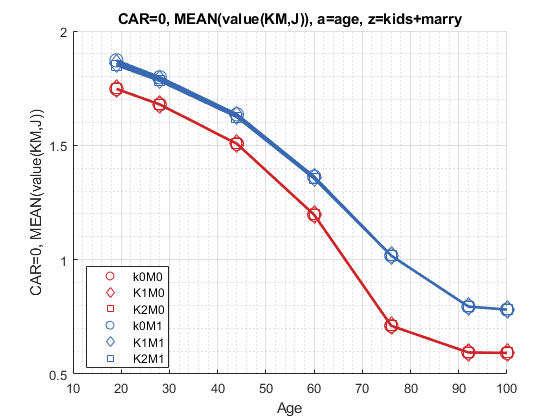

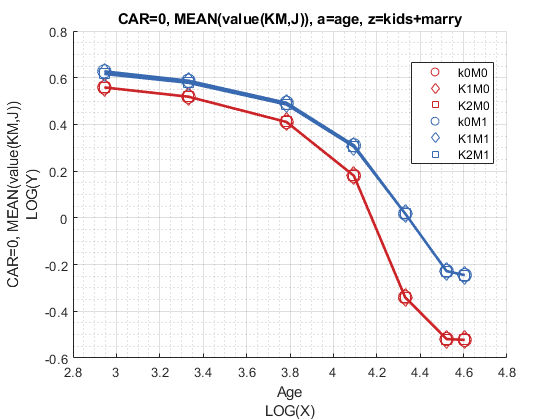

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(value(KM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(value(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

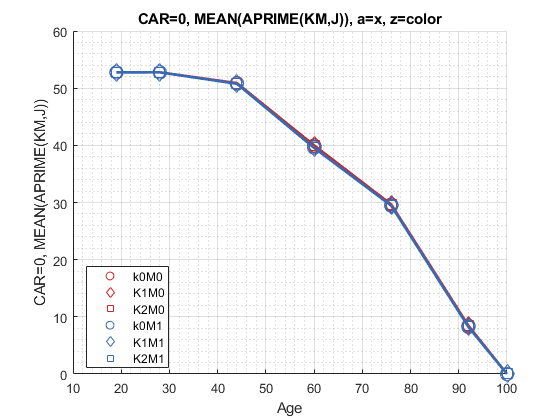

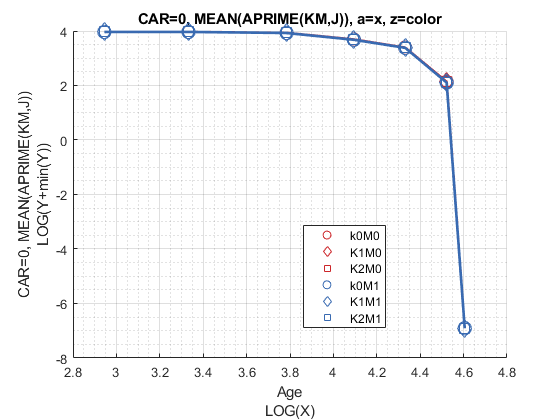

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(APRIME(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(APRIME(KM,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

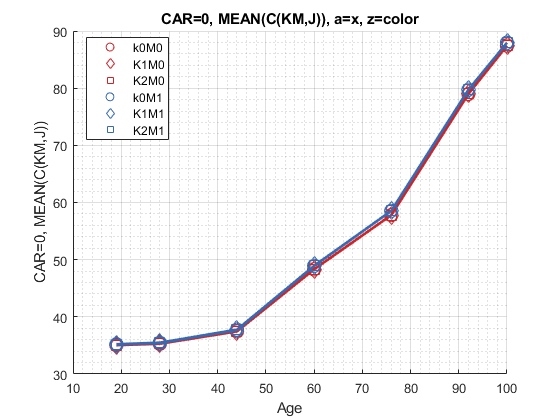

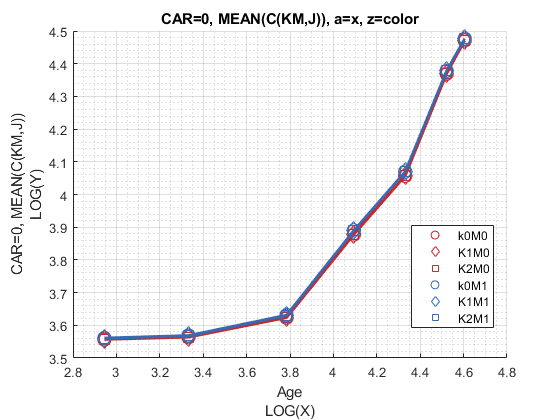

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(C(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(C(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EKM,J)), MEAN(AP(EKM,J)), MEAN(C(EKM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(EKM,J))", V_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        1.7121         1.6279         1.4565         1.1565         0.68704        0.57865        0.57715   
      2       1       0        1.7817         1.7298         1.5564         1.2369         0.73429         0.6097        0.60701   
      3       0       1        1.8263         1.7454         1.5887         1.32

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(EKM,J))", ap_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        52.778         52.777         50.838         39.892         29.655         8.4444            0      
      2       1       0         52.76         52.775         50.912         40.077         29.638         8.4444            0      
      3       0       1        52.774         52.772         50.748         39.51

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(EKM,J))", cons_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        35.037         35.185         37.306         48.234         57.766         78.977          87.421   
      2       1       0        35.055         35.391         37.607         48.389         57.819         79.013          87.458   
      3       0       1         35.16         35.325         37.547         48.775

Graph Mean Values:

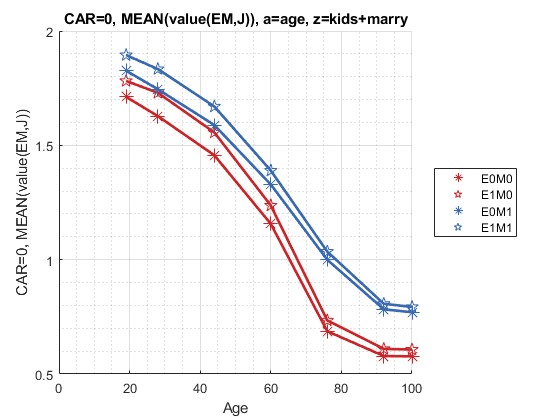

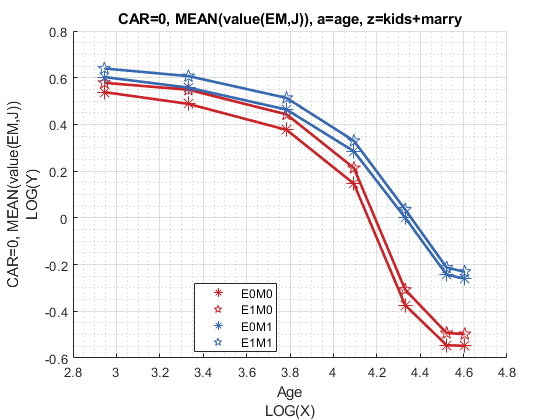

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(value(EM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(value(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

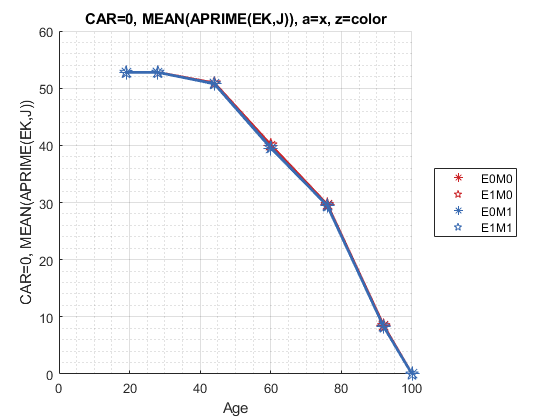

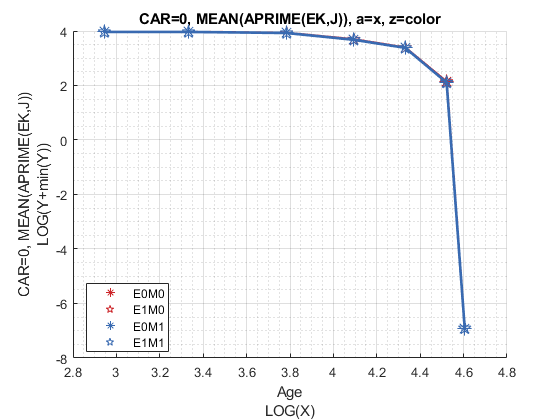

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(APRIME(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(APRIME(EK,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

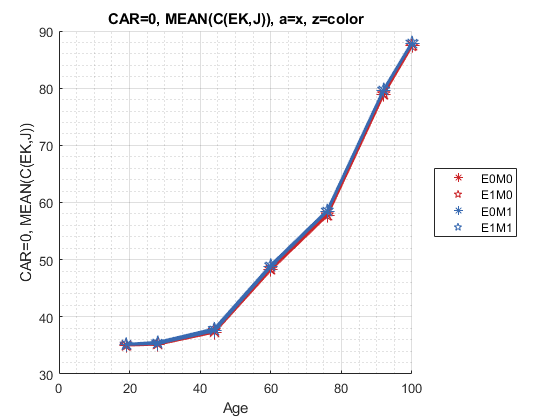

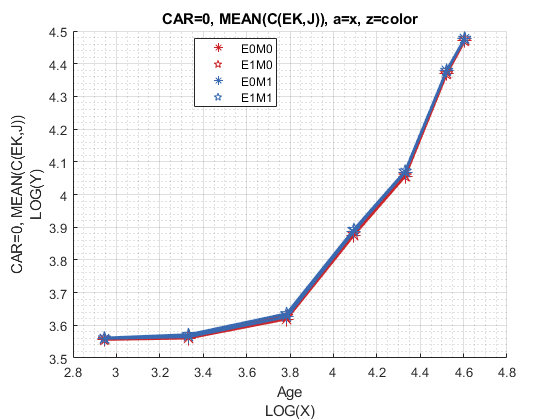

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(C(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(C(EK,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);